% Parameters for the normal distribution
mu = 0; % Mean
sigma = 1; % Standard deviation

% Range for x-axis
x = linspace(mu - 4*sigma, mu + 4*sigma, 1000);

% PDF of the normal distribution
pdf = (1/(sigma*sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);

% Plot the PDF
figure;
plot(x, pdf, 'LineWidth', 1.5);
hold on;

% Define the range [a, b]
a = -1;
b = 1;

% Highlight the area under the curve for a ≤ x ≤ b
x_fill = x(x >= a & x <= b);
pdf_fill = pdf(x >= a & x <= b);
fill([x_fill fliplr(x_fill)], [pdf_fill zeros(size(pdf_fill))], 'r', 'FaceAlpha', 0.5);

% Labels and title
xlabel('x');
ylabel('Probability Density');
title('Normal Distribution PDF with Highlighted Area');

% Calculate and display the probability for a ≤ x ≤ b
prob = normcdf(b, mu, sigma) - normcdf(a, mu, sigma);
disp(['Probability of x being in the range [', num2str(a), ', ', num2str(b), '] is: ', num2str(prob)]);

Probability of x being in the range [-1, 1] is: 0.68269


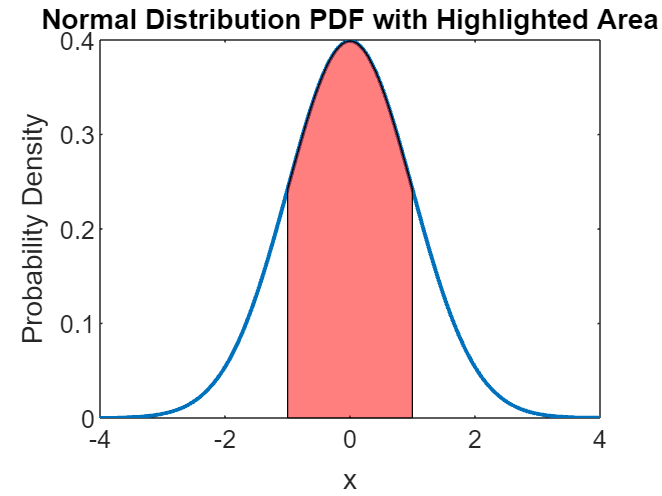

hold off;